# Lab 2A: Demodulating data from a MIMO communication system

load("2User2AntennaBS.mat")

#### Accounting for minor lag

The xcorr function was used to determine the lag between the transmitter and receiver. It takes the cross correlation of the transmitted and received signal using the 128 known random bits from x1/x2

[y1x1,lag1] = xcorr(y1,x1); 
[~, Index1] = max(abs(y1x1));
shift1 = lag1(Index1)

shift1 = 20


[y2x2,lag2] = xcorr(y2,x2);
[~, Index2] = max(abs(y2x2));
shift2 = lag2(Index2)

shift2 = 20

%Note how the lag is the same for both receivers

Shift received data with calcualted lag

y1 = [y1(shift1:end) ; zeros(shift1-1,1)];
y2 = [y2(shift2:end) ; zeros(shift2-1,1)];

Obtaining White Noise Sample

y1_noise = y1(1:5001);
y2_noise = y2(1:5001);

Obtaining Original Data

%Creating markers to indicate where data transmission starts and stops
buffer_zero = 5000; 
R_128 = 5120;
R_1024 = 40960;

Data1 = x1(3*buffer_zero + 2* R_128 + 20: 40: 3*buffer_zero + 2*R_128+ R_1024);
Data2 = x2(3*buffer_zero + 2* R_128 + 20: 40: 3*buffer_zero + 2*R_128+ R_1024);

Plotting Data

figure

%plotting Transmitted data from transmitter 1
subplot(2,2,1)
stem(x1)
xlabel('bits')
ylabel('Amplitude')
xline(buffer_zero + 1,'r')
xline(buffer_zero + R_128,'r')
xline(3*buffer_zero + 2* R_128 + 20,'r')
xline(3*buffer_zero + 2*R_128+ R_1024,'r')
title('i.) Transmitted data from transmitter 1')

%plotting Transmitted data from transmitter 2
subplot(2,2,2)
stem(x2)
xlabel('bits')
ylabel('Amplitude')
xline(2*buffer_zero + R_128 + 1)
xline(2*buffer_zero + 2*R_128)
xline(3*buffer_zero + 2* R_128 + 20,'r')
xline(3*buffer_zero + 2*R_128+ R_1024,'r')
title('ii.) Transmitted data from transmitter 2')

%plotting received data from receiver 1
subplot(2,2,3)
stem(y1)

xlabel('bits')
ylabel('Amplitude')
xline(buffer_zero + 1,'r')
xline(buffer_zero + R_128,'r')
xline(3*buffer_zero + 2* R_128 + 20,'r')
xline(3*buffer_zero + 2*R_128+ R_1024,'r')
title('iii.) Received data from receiver 1')

%plotting received data from receiver 2
subplot(2,2,4)
stem(y2)

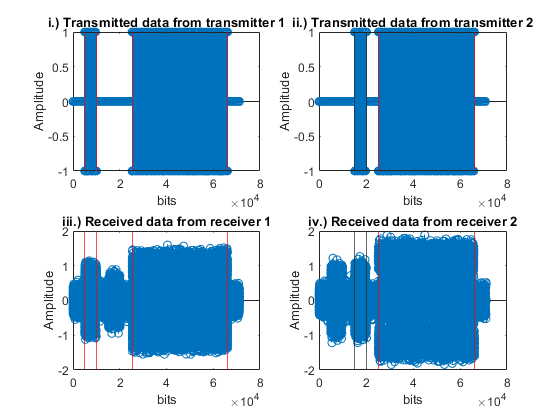

xlabel('bits')
ylabel('Amplitude')
xline(2*buffer_zero + R_128 + 1)
xline(2*buffer_zero + 2*R_128)
xline(3*buffer_zero + 2* R_128 + 20,'r')
xline(3*buffer_zero + 2*R_128+ R_1024,'r')
title('iv.) Received data from receiver 2')

#### Obtaining 128 random bits: 

These bits are our only known values. Random_x1/x2 are the known random 128 bit array that the receiver will also know

%Transmitted 
Random_x1 = x1(buffer_zero + 1 : buffer_zero + R_128);
Random_x2 = x2(2*buffer_zero + R_128 + 1: 2*buffer_zero + 2*R_128);

%Received
Random_y1 = y1(buffer_zero+1:buffer_zero+R_128);
Random_y2 = y2(2*buffer_zero+R_128+1:2*buffer_zero+2*R_128);

#### Obtaining the H matrix:

This matrix describes the system based off of comparing the values to returned values, giving us an idea of the environment -> transfer function

%Calculates transfer function by getting the average H[k] along each array
H11 = mean(Random_y1 ./ Random_x1);        %h11: Transfer function between received signal y1 and transmitted x1
H12 = mean(Random_y1 ./ Random_x2);        %h12: Transfer function between received signal y1 and transmitted x2
H21 = mean(Random_y2 ./ Random_x1);        %h21: Transfer function between received signal y2 and transmitted x1
H22 = mean(Random_y2 ./ Random_x2);        %h22: Transfer function between received signal y2 and transmitted x2

H = [H11 H12 ; H21 H22]             %matrix for Receiver 1

H =   -0.6280 - 0.2608i  -0.0789 - 0.0334i
  -0.0780 - 0.0070i  -0.6404 - 0.0959i


H2 = [H22 H21 ; H12 H11]            %matrix for Receiver 2

H2 =   -0.6404 - 0.0959i  -0.0780 - 0.0070i
  -0.0789 - 0.0334i  -0.6280 - 0.2608i



y = [y1 ; y2];
x = [x1 ; x2];

### Using Zero-Force equalization to decode Signal from Receiver 1

Calculate the weight vector

w = (transpose(conj(H))) \ [1 ; 0];
Identity_Confirm = transpose(conj(H))* w %confirming relationship where w * H^H equals an identity matrix

Identity_Confirm =    1.0000 - 0.0000i
   0.0000 - 0.0000i


Estimate x

x_est =  transpose(conj(w)).*(y1);

x1_est = x_est(:,1);                   %Obtains x1
x2_est = x_est(:,2);                   %Obtains x2

Plotting Results

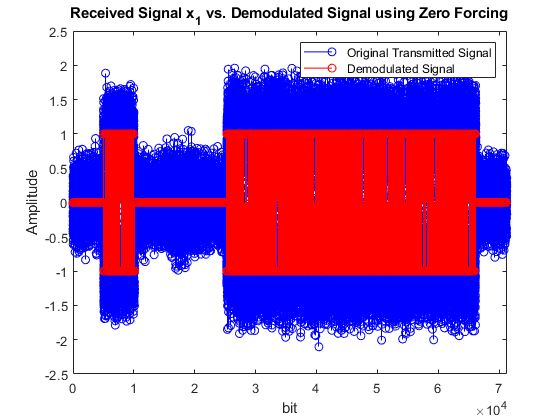

stem(real(x1_est),'b')
hold on
stem(real(x1),'r')
legend('Original Transmitted Signal','Demodulated Signal')
xlim([0,71298])
xlabel('bit')
ylabel('Amplitude')
title('Received Signal x_{1} vs. Demodulated Signal using Zero Forcing')
hold off

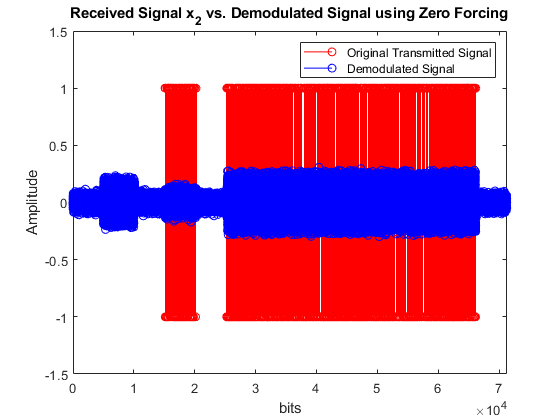


stem(real(x2),'r')
hold on
stem(real(x2_est),'b')
legend('Original Transmitted Signal','Demodulated Signal')
xlim([0,71298])
ylim([-1.5,1.5])
xlabel('bits')
ylabel('Amplitude')
title('Received Signal x_{2} vs. Demodulated Signal using Zero Forcing')
hold off

### Using Zero-Force equalization to decode Signal from Receiver 2

Calculate the weight vector

w2 = (transpose(conj(H))) \ [0 ; 1];

Identity_Confirm = transpose(conj(H))* w2 %confirming relationship where w * H^H equals an identity matrix

Identity_Confirm =    0.0000 - 0.0000i
   1.0000 + 0.0000i


Estimate x

x_est =  transpose(conj(w2)).*(y2);
x2_est = x_est(:,2);                   %Obtains x2

Plotting Results

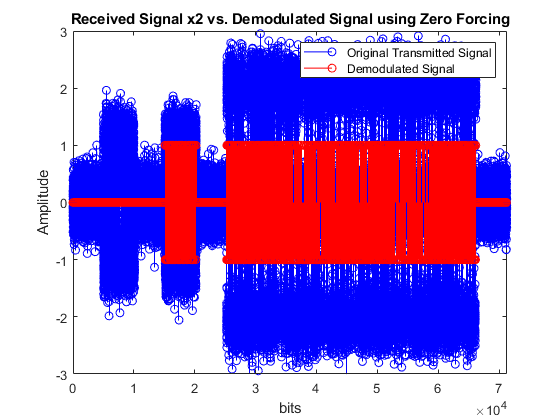

%Plotting for x2
%x2_est = x2_./(max(real(x2_)));
stem(real(x2_est),'b')
hold on
stem(real(x2),'r')
legend('Original Transmitted Signal','Demodulated Signal')
xlim([0,71298])
ylim([-3,3])
xlabel('bits')
ylabel('Amplitude')
title('Received Signal x2 vs. Demodulated Signal using Zero Forcing')
hold off

### MMSE

#### Calculate variance of noise

Var_Noise = var(y1_noise);
Var_Noise2 = var(y2_noise);
Var_y1 = var(Random_y1);
Var_x1 = var(Random_x1);
Var_x2 = var(Random_x2);

#### Estimating x1 

Creating the Weight Matrix using the equation:

wmmse = transpose(conj(H))./( H .* transpose(conj(H)) + ((Var_Noise/Var_x1) * [1 0 ;0 1]))  * [1 ; 0];


#### Obtaning the Estimate of X1

x_est_MMSE = (y1) * transpose(wmmse);
x1_est_MMSE = x_est_MMSE(:,1);                   %Obtains x1

Plot

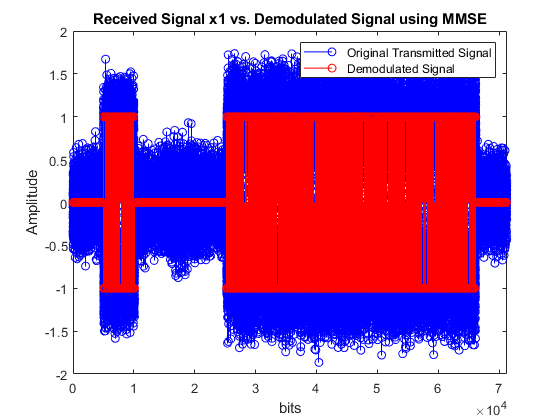

figure
stem(real(x1_est_MMSE),'b')
hold on
stem(real(x1),'r')
title('Received Signal x1 vs. Demodulated Signal using MMSE')
legend('Original Transmitted Signal','Demodulated Signal')
xlim([0,71298])
ylim([-2,2])
xlabel('bits')
ylabel('Amplitude')
hold off

#### Obtaning the Estimate of X2

wmmse = transpose(conj(H))./( H .* transpose(conj(H)) + ((Var_Noise2/Var_x2) * [1 0 ;0 1]))  * [1 ; 0];
x_est_MMSE = transpose(conj(wmmse)).*y2;
x2_est_MMSE = x_est_MMSE(:,2);                   %Obtains x2

Plot

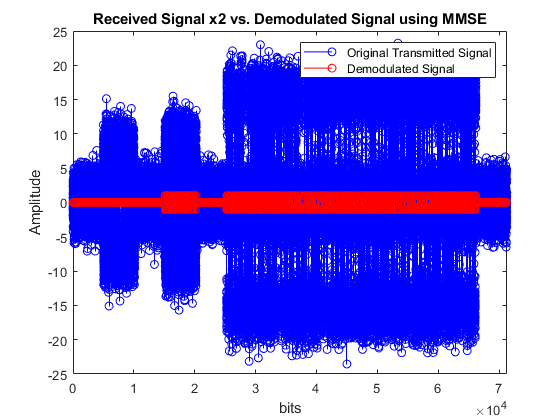

stem(real(x2_est_MMSE),'b')
hold on
stem(real(x2),'r')
legend('Original Transmitted Signal','Demodulated Signal')
xlim([0,71298])
title('Received Signal x2 vs. Demodulated Signal using MMSE')
xlabel('bits')
ylabel('Amplitude')
hold off

Zoomed in Data

figure
subplot(2,2,1)
stem(x1_est)

hold on
xlabel('bits')
ylabel('Amplitude')
xlim([30000,32500])
ylim([-.3,.3])
title('i.) Retrieved x_{1} using Zero Force')
hold off

subplot(2,2,2)
stem(x2_est)

xlabel('bits')
ylabel('Amplitude')
xlim([30000,32500])
ylim([-.3,.3])
title('ii.) Retrieved x_{2} using Zero Force')

subplot(2,2,3)
stem(x1_est_MMSE)

xlabel('bits')
ylabel('Amplitude')
xlim([30000,32500])
ylim([-.3,.3])
title('iii.) Retrieved x_{1} using MMSE')

subplot(2,2,4)
stem(x2_est_MMSE)

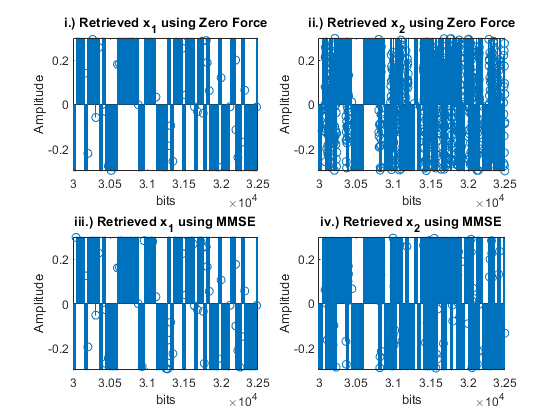

xlabel('bits')
ylabel('Amplitude')
xlim([30000,32500])
ylim([-.3,.3])
title('iv.) Retrieved x_{2} using MMSE')

#### Error Rate For obtaining X1

#### Zero-Forcing

Calculating Error From Data extracted from the 40 bit pulses

Data1_est_R1 = real(x1_est(3*buffer_zero + 2* R_128 + 20: 40: 3*buffer_zero + 2*R_128+ R_1024));
Data2_est_R2 = real(x2_est(3*buffer_zero + 2* R_128 + 20: 40: 3*buffer_zero + 2*R_128+ R_1024));


diff_1 = real((Data1 - (Data1_est_R1./abs(Data1_est_R1))))./Data1;
Error_X1_ZF = abs(mean(diff_1)) *100

Error_X1_ZF = 0


diff_2 = real((Data2 - (Data2_est_R2./abs(Data2_est_R2))))./Data2;
Error_X2_ZF = abs(mean(diff_2)) *100

Error_X2_ZF = 47.6563

#### MMSE

Calculating Error From Data extracted from the 40 bit pulses

Data1_est_R1MMSE = real(x1_est_MMSE(3*buffer_zero + 2* R_128 + 20: 40: 3*buffer_zero + 2*R_128+ R_1024));
Data2_est_R2MMSE = real(x2_est_MMSE(3*buffer_zero + 2* R_128 + 20: 40: 3*buffer_zero + 2*R_128+ R_1024));

diff2 = real((Data1 - (Data1_est_R1MMSE./abs(Data1_est_R1MMSE))))./Data1;
Error_X1_MMSE = abs(mean(diff2))*100

Error_X1_MMSE = 0



diff_2 = real((Data2 - Data2_est_R2MMSE./abs(Data2_est_R2MMSE)))./Data2;
Error_X2_MMSE = abs(mean(diff2))*100

Error_X2_MMSE = 0